# Análise de sinais de voz

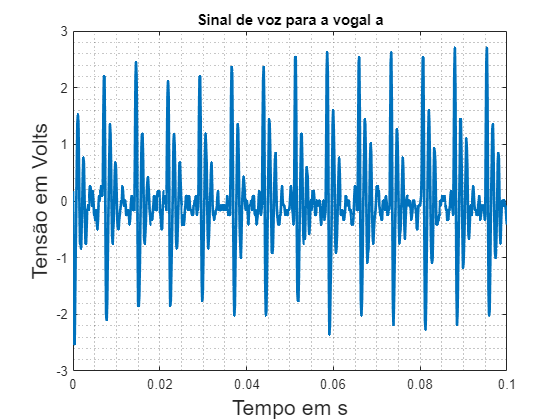

%%% Incia o ambiente matlab para uma sessão de análises

clear; clc; close all;

%%% Carrega o trabalho feito anteriormente e gravado no arquivo Voz.mat

load('Voz.mat')

% Cria uma figura para a análise temporal

plot(t,Vp,'LineWidth', 2);
title('Sinal de voz para a vogal a');
xlabel('Tempo em s', 'FontSize', 16,'LineWidth',2);
ylabel('Tensão em Volts', 'FontSize', 16,'LineWidth',2); 
grid minor


% plot(frequencia,Y0, 'LineWidth', 2);
% title('Espectro de amplitude da vogal a');
% xlabel('Frequência em Hz', 'FontSize', 16,'LineWidth',2);
% ylabel('Magnitude em dB', 'FontSize', 16,'LineWidth',2); 
% grid minor

a = transpose(findpeaks(Vp,t,'MinPeakDistance',0.0011264, 'MinPeakHeight', 1.52458))

a =     1.5246    2.1993    2.4524    2.1150    2.1993    2.3680    2.3680    2.5367    2.6211    1.6089    2.5367    2.6211    2.5367    1.6089    2.7054    2.7054



for i = 1:length(a)
    b(i)=find(Vp==a(i),1);
    d(i)=find(Vp==a(i),1);
    
    c(i)=t(b(i));
end

b

b =     10    58   117   116    58   293   293   410   469    57   410   469   410    57   704   704


c

c =     0.0011    0.0071    0.0145    0.0144    0.0071    0.0365    0.0365    0.0512    0.0586    0.0070    0.0512    0.0586    0.0512    0.0070    0.0880    0.0880


ti = c(1)

ti = 0.0011

tf = c(length(c))

tf = 0.0880

T = (ti+tf)/length(c)

T = 0.0056

f = inv(T)

f = 179.5506